clear;clc;clf;
% Data from 5/30/2023 - Forresti
format short g ; format compact 
folder_path = "/Users/nbonnie/Desktop/FF_Stereo_Calibration_Free/";
fnames = dir(strcat(folder_path,"*.mat"))

fnames = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum

addpath(genpath(folder_path))
data1 = load(strcat(folder_path, fnames(1).name));
data2 = load(strcat(folder_path, fnames(2).name));
fns1 = fieldnames(data1);
fns2 = fieldnames(data2);

df1 = data1.(fns1{1}).xyt;
df2 = data2.(fns2{1}).xyt;
c1n = data1.(fns1{1}).n;
c2n = data2.(fns2{1}).n;

frame_width = data1.(fns1{1}).mov.Width;

frame_width =         1920

frame_height = data1.(fns1{1}).mov.Height;

frame_height =         1080

c1_start = 3384;
c2_start = 2862;
dk = c2_start - c1_start;
% dkRobust.m not working for stereo
% [dk, dkRes] = dkRobust(c1n, c2n)

% Find 1 sync frames to calibrate on:
calTraj = extractCalibrationTrajectories(df1,df2,dk);

% Code in git will not run as is- extractCalTraj has been updated, but not
% in the main file "reconstruct360.m"
% [calTraj1,calTraj2] = extractCalibrationTrajectories(df1,df2,dk);

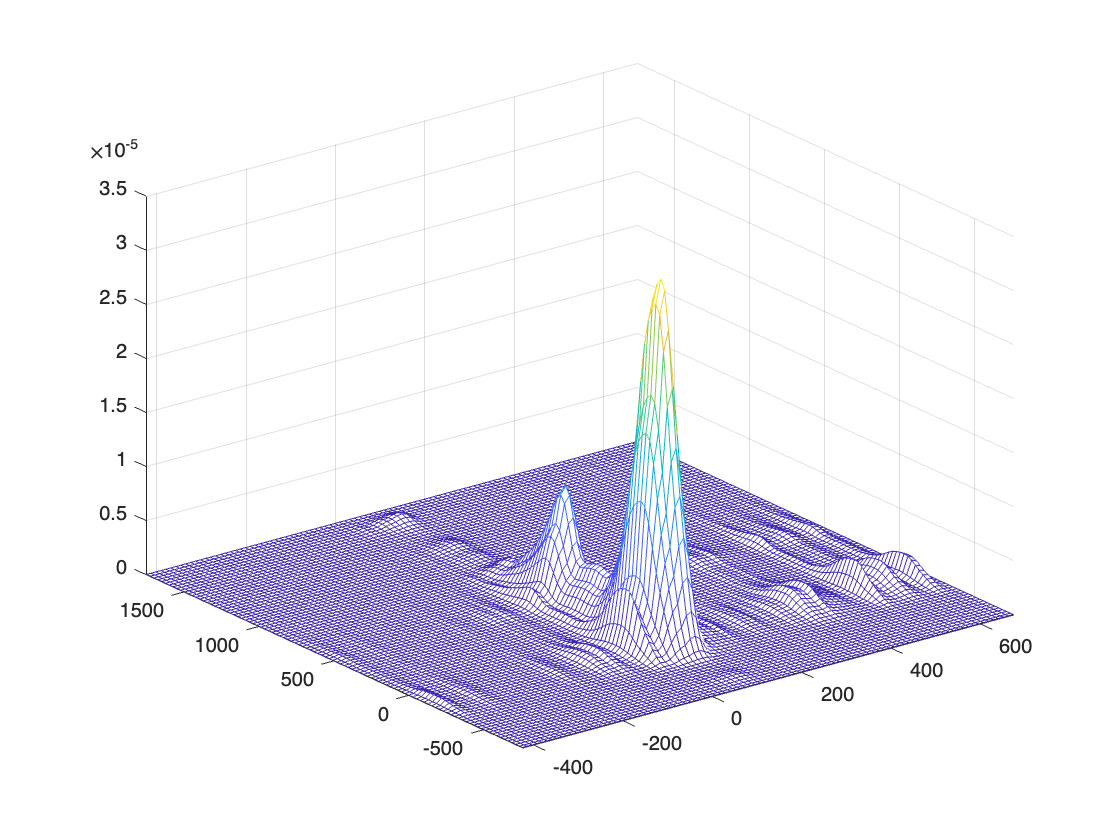

% Pin all points from C1 at 0,0 - plot all C2 displatement relative to C1
displacements = zeros(size(calTraj.j1, 1),2);
for i = 1:size(displacements,1)
    % X2 - X1, Y2 - Y1
    displacements(i,:) = [calTraj.j2(i,2)-calTraj.j1(i,2), calTraj.j2(i,1)-calTraj.j1(i,1)];
end

% Construct pdf for X & Y vars, plot

% Estimate a continuous pdf from the discrete data
[pdfx, xi]= ksdensity(displacements(:,1));
[pdfy, yi]= ksdensity(displacements(:,2));
% Create 2-d grid of coordinates and function values, suitable for 3-d plotting
[xxi,yyi]     = meshgrid(xi,yi);
[pdfxx,pdfyy] = meshgrid(pdfx,pdfy);
% Calculate combined pdf, under assumption of independence
pdfxy = pdfxx.*pdfyy; 
% Plot the results
mesh(xxi,yyi,pdfxy)
set(gca,'XLim',[min(xi) max(xi)])
set(gca,'YLim',[min(yi) max(yi)])